# Process the intensity data from Idler

Theta = (0,2) degrees.

cylinder_dimer_no_substrate_111_6


ans =           4348668045.51306


ans =           2812.95446922285


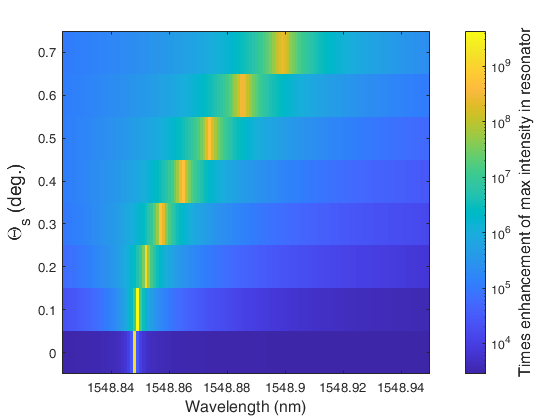

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed');

cylinder_dimer_no_substrate_110_13 = ["cylinder_dimer_no_substrate_110_13_1",...
    "cylinder_dimer_no_substrate_110_13_2","cylinder_dimer_no_substrate_110_13_3",...
    "cylinder_dimer_no_substrate_110_13_4","cylinder_dimer_no_substrate_110_13_5",...
    "cylinder_dimer_no_substrate_110_13_6","cylinder_dimer_no_substrate_110_13_7",...
    "cylinder_dimer_no_substrate_110_13_8","cylinder_dimer_no_substrate_110_13_9",...
    "cylinder_dimer_no_substrate_110_13_11","cylinder_dimer_no_substrate_110_13_12"];
cylinder_dimer_no_substrate_110 = ["cylinder_dimer_no_substrate_110_2",...
    "cylinder_dimer_no_substrate_110_3","cylinder_dimer_no_substrate_110_4",...
    "cylinder_dimer_no_substrate_110_5","cylinder_dimer_no_substrate_110_6",...
    "cylinder_dimer_no_substrate_110_7","cylinder_dimer_no_substrate_110_8",...
    "cylinder_dimer_no_substrate_110_9","cylinder_dimer_no_substrate_110_10"];


max_enhancement = 1e-20;
min_enhancement = 1e40;

%for job = "kerker_slab_silicon_1_1"
for job = "cylinder_dimer_no_substrate_111_6"
%for job = "slab_dimer_no_substrate_111_28"
    eval(job);
    load([options.output_dir_final 'sweep_data.mat']);
    extra_options = matthew_extra_options(options);
    disp(job);
    scat_eff = [];
    scat_eff2 = [];
    scat_eff3 = [];
    y_axis = [];
    
    for study_num = 1:height(sweep_data)
        derived_values = sweep_data(study_num,:).DerivedValues{1};
        
        wlengths = (299792458./derived_values.signal.freq)';
        
        %scat_eff = [scat_eff; derived_values.signal.scat_eff'];
        scat_eff = [scat_eff; derived_values.signal.max_Is'/derived_values.parameters.I0];
        %scat_eff = [scat_eff; ((derived_values.signal.sigma_fullup)+(derived_values.signal.sigma_fulldn))'];
        %scat_eff2 = [scat_eff2; (derived_values.signal.max_Is)'];
        scat_eff2 = [scat_eff2; ((derived_values.signal.sigma_scdn)/derived_values.signal.surface_area(1))'];
        scat_eff3 = [scat_eff3; ((derived_values.signal.sigma_scup)/derived_values.signal.surface_area(1))'];
        y_axis = [y_axis, derived_values.parameters.theta*180/pi];
        %y_axis = [y_axis, derived_values.parameters.r_bar*1e9];
        %y_axis = [y_axis, derived_values.parameters.D*1e9];
        %y_axis = [y_axis, derived_values.parameters.gap*1e9];
        %scat_eff = [scat_eff; log10(derived_values.sfg.scat3_eff)'];
        %y_axis = [y_axis, derived_values.parameters.scale];
        

        if max(derived_values.signal.max_Is/derived_values.parameters.I0) > max_enhancement
            max_enhancement = max(derived_values.signal.max_Is/derived_values.parameters.I0);
        end
        if min(derived_values.signal.max_Is/derived_values.parameters.I0) < min_enhancement
            min_enhancement = min(derived_values.signal.max_Is/derived_values.parameters.I0);
        end
    end
    max(max(scat_eff))
    min(min(scat_eff))
    fig = figure;
    [X,Y] = meshgrid(wlengths, y_axis);
   
    %surf(X,Y, scat_eff); 
    imagesc(wlengths, y_axis, scat_eff);
    axis([wlengths(end) 1548.95 -0.05 0.75]);
    xlabel('Wavelength (nm)', 'FontSize', 12);
    ylabel('\Theta_s (deg.)', 'FontSize', 14);
    %ylabel('\Lambda (nm)');
    %ylabel('r_{bar} (nm)');
    %ylabel('gap (nm)');
    %ylabel('Hole radius (nm)');
    axis tight;
    cb = colorbar;
    %ylabel(cb, 'log_{10}(SFG Emission)');
    ylabel(cb, 'Times enhancement of max intensity in resonator', 'FontSize', 12);
    set(gca,'ColorScale','log');
    caxis([min_enhancement max_enhancement]);
    %title(strcat('\Theta = ', num2str((theta_ind-1)*0.1), ' deg.'));
    %title(job, 'Interpreter', 'none');
    view(0,-90);
    axis([wlengths(end) 1548.95 -0.05 0.75]);
    %{
    figure;
    imagesc(wlengths, y_axis, scat_eff2);
    xlabel('Wavelength (nm)');
    %ylabel('Theta (deg.)');
    ylabel('\Lambda (nm)');
    %ylabel('r_{bar} (nm)');
    %ylabel('gap (nm)');
    %ylabel('Hole radius (nm)');
    axis tight;
    cb = colorbar;
    ylabel(cb, 'log_{10}(SFG Emission)');
    %ylabel(cb, 'Linear scattering efficiency');
    %title(strcat('\Theta = ', num2str((theta_ind-1)*0.1), ' deg.'));
    title('down');
    figure;
    imagesc(wlengths, y_axis, scat_eff3);
    xlabel('Wavelength (nm)');
    ylabel('Theta (deg.)');
    %ylabel('r_{bar} (nm)');
    %ylabel('gap (nm)');
    %ylabel('Hole radius (nm)');
    axis tight;
    cb = colorbar;
    ylabel(cb, 'log_{10}(SFG Emission)');
    %ylabel(cb, 'Linear scattering efficiency');
    %title(strcat('\Theta = ', num2str((theta_ind-1)*0.1), ' deg.'));
    title('up');
    %}
    saveas(fig, strcat("C:\Users\Matthew\Downloads\",job), 'png');
end